% Assignment 2
% Name: Xinran Zhao
% UCD: 23219923

% Task 1.1: Theoretical Calculation of Fourier Coefficients

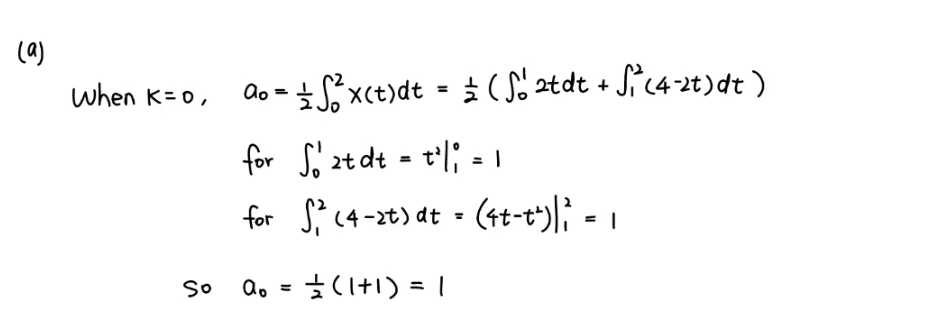

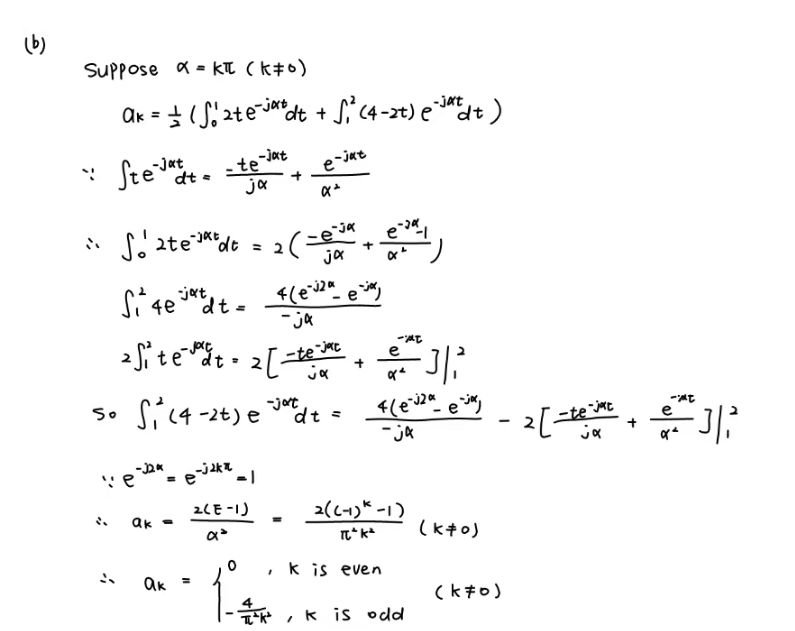

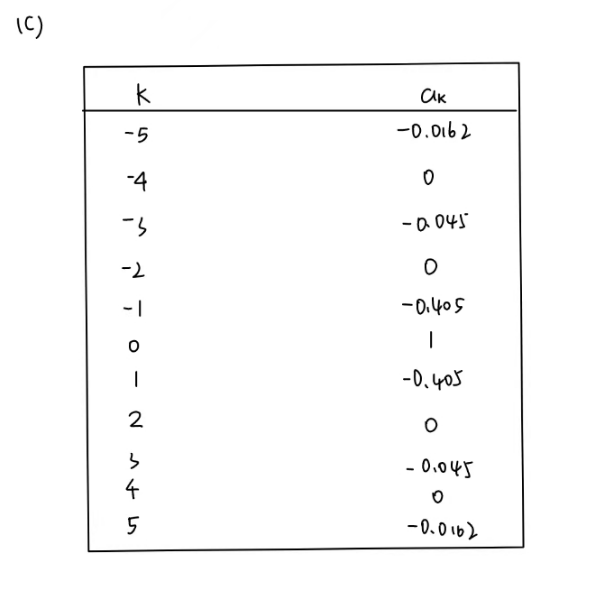

% Task 1.2: MATLAB implementation of Fourier coefficients a_k (numerical)
clear; clc;                                  % Clear workspace and command window

T = 2;                                       % Set signal period T = 2
w0 = 2*pi/T;                                 % Fundamental angular frequency w0 = pi
k_vec = (-5:5).';                            % Column vector of harmonic indices k

dt = 1e-4;                                  % Time step for numerical integration
t = 0:dt:T;                                 % Time vector over one period [0, T]
t(end) = [];                                % Remove endpoint to avoid duplication

x = zeros(size(t));                          % Preallocate signal x(t)
idx1 = (t >= 0) & (t < 1);                   % Logical index for interval [0, 1)
idx2 = (t >= 1) & (t < 2);                   % Logical index for interval [1, 2)
x(idx1) = 2*t(idx1);                         % Define x(t) = 2t on [0, 1)
x(idx2) = 4 - 2*t(idx2);                     % Define x(t) = 4 - 2t on [1, 2)

a_num = zeros(length(k_vec),1);              % Preallocate numerical Fourier coefficients

for ii = 1:length(k_vec)                     % Loop over all k values
    k = k_vec(ii);                           % Extract current harmonic index
    integrand = x .* exp(-1j*k*w0*t);        % Compute integrand x(t)e^{-jkω0t}
    a_num(ii) = (1/T)*trapz(t, integrand);   % Numerical integration using trapz
end

% Task 1.2(b): Theoretical Fourier coefficients and comparison
a_theory = zeros(length(k_vec),1);            % Preallocate theoretical coefficients

for ii = 1:length(k_vec)                     % Loop over all k values
    k = k_vec(ii);                           % Extract current harmonic index
    if k == 0                                % DC component
        a_theory(ii) = 1;                    % a0 = 1
    elseif mod(k,2) == 0                     % Even harmonic (k ≠ 0)
        a_theory(ii) = 0;                    % Even coefficients are zero
    else                                     % Odd harmonic
        a_theory(ii) = -4/(pi^2*k^2);        % Formula for odd Fourier coefficients
    end
end

abs_err = abs(a_num - a_theory);              % Compute absolute error
pct_err = zeros(size(abs_err));               % Preallocate percentage error array

for ii = 1:length(k_vec)                     % Loop over error computation
    if abs(a_theory(ii)) < 1e-12              % Check for near-zero theoretical value
        pct_err(ii) = NaN;                   % Percentage error undefined for zero theory
    else
        pct_err(ii) = abs_err(ii)/abs(a_theory(ii))*100; % Compute percentage error
    end
end

result_table = table(k_vec, a_theory, a_num, pct_err, ... % Create comparison table
    'VariableNames', {'k','a_k_theory','a_k_numeric','percent_error'}); % Set column names

disp(result_table);                           % Display results table

    k     a_k_theory         a_k_numeric         percent_error
    __    __________    _____________________    _____________

    -5    -0.016211     -0.016211+7.8539e-12i     5.1404e-05  
    -4            0        -5e-09+6.2833e-12i            NaN  
    -3    -0.045032     -0.045032+4.7124e-12i     1.8506e-05  
    -2            0        -5e-09+3.1415e-12i            NaN  
    -1     -0.40528      -0.40528+1.5709e-12i     2.0562e-06  
     0            1             1+0i                   5e-07  
     1     -0.40528      -0.40528-1.5709e-12i     2.0562e-06  
     2            0        -5e-09-3.1415e-12i            NaN  
     3    -0.045032     -0.045032-4.7124e-12i     1.8506e-05  
     4            0        -5e-09-6.2833e-12i            NaN  
     5    -0.016211     -0.016211-7.8539e-12i     5.1404e-05  



**( C ) Discussion on the Agreement Between Theoretical and Numerical Results**

The numerically computed Fourier coefficients are in very good agreement with the theoretical values derived in Task 1.1. In particular, the DC component a0a_0a0� obtained from numerical integration closely matches the theoretical value of 1, indicating correct implementation of the Fourier coefficient formula.

For even values of k≠0, the theoretical coefficients are zero, and the numerical results are also close to zero, with only very small residual values. These small discrepancies arise from numerical integration and floating-point rounding errors.

For odd values of kkk, the numerical coefficients closely follow the theoretical expression. The remaining errors are small and decrease as the integration step size is reduced, confirming the accuracy of the numerical approach.

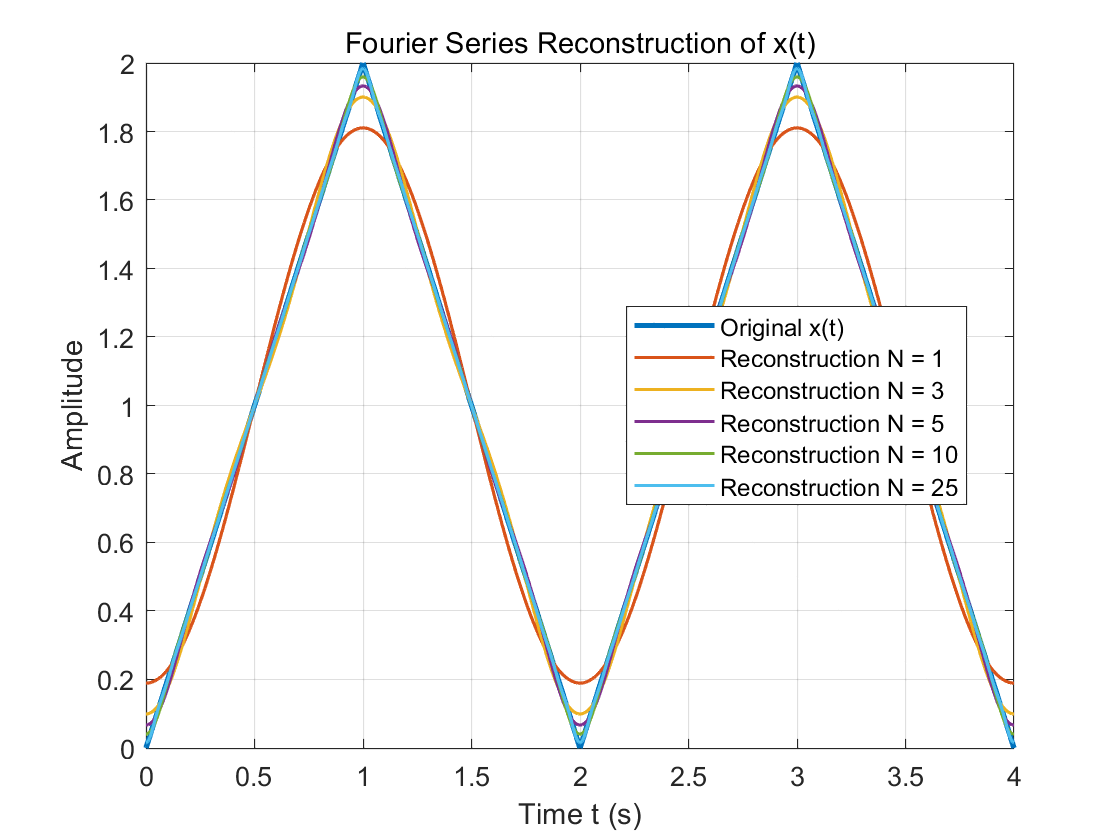

% Task 1.3: Signal Reconstruction Using Fourier Series
% Task 1.3(a)
clear; clc;                                      % Clear workspace and command window

T = 2;                                           % Define signal period T = 2 seconds
w0 = 2*pi/T;                                     % Fundamental angular frequency w0 = pi

dt = 1e-3;                                       % Time step for plotting resolution
t = 0:dt:4;                                      % Time vector over two periods [0, 4]

x = zeros(size(t));                              % Preallocate original signal array
t_mod = mod(t, T);                               % Map time to one-period interval [0, T)

idx1 = (t_mod >= 0) & (t_mod < 1);               % Logical index for first segment
idx2 = (t_mod >= 1) & (t_mod < 2);               % Logical index for second segment
x(idx1) = 2 * t_mod(idx1);                       % Define x(t) = 2t for 0 <= t < 1
x(idx2) = 4 - 2 * t_mod(idx2);                   % Define x(t) = 4 - 2t for 1 <= t < 2

N_list = [1 3 5 10 25];                          % Truncation orders to be evaluated
x_rec = zeros(length(N_list), length(t));        % Preallocate reconstructed signals

for n_idx = 1:length(N_list)                     % Loop over different truncation orders
    N = N_list(n_idx);                           % Current truncation order
    k_vec = -N:N;                                % Harmonic indices from -N to N
    xN = zeros(size(t));                         % Initialize reconstructed signal
    
    for k = k_vec                                % Loop over each harmonic index
        if k == 0                                % Check for DC component
            ak = 1;                              % Set a0 = 1 from theoretical result
        elseif mod(k,2) == 0                     % Check for even harmonic (k ≠ 0)
            ak = 0;                              % Even harmonics are zero
        else                                     % Odd harmonic case
            ak = -4 / (pi^2 * k^2);              % Theoretical coefficient for odd k
        end
        
        xN = xN + ak * exp(1j * k * w0 * t);     % Add k-th Fourier term to reconstruction
    end
    
    x_rec(n_idx, :) = real(xN);                  % Store real part of reconstructed signal
end

% Task 1.3(b)
figure;                                          % Create a new figure window
plot(t, x, 'LineWidth', 2);                      % Plot original signal with thick line
hold on;                                         % Hold plot for overlaying curves

for n_idx = 1:length(N_list)                     % Loop over all reconstruction orders
    plot(t, x_rec(n_idx,:), 'LineWidth', 1.2);   % Plot reconstructed signal for current N
end

grid on;                                         % Enable grid for better visualization
xlabel('Time t (s)');                            % Label x-axis
ylabel('Amplitude');                             % Label y-axis
title('Fourier Series Reconstruction of x(t)');  % Add descriptive title

legend_entries = cell(1, 1 + length(N_list));    % Preallocate legend text cell array
legend_entries{1} = 'Original x(t)';             % Legend entry for original signal

for n_idx = 1:length(N_list)                     % Loop to generate legend entries
    legend_entries{1 + n_idx} = ...              
        sprintf('Reconstruction N = %d', N_list(n_idx)); % Label for each reconstruction
end

legend(legend_entries, 'Location', 'best');      % Display legend at optimal location
hold off;                                        % Release plot hold

**( C ) Discussion:**

As the truncation order NNN increases, the reconstruction becomes closer to the original triangular waveform, especially along the linear segments. Higher NNN includes more harmonics, which improves the ability of the Fourier series to represent sharper changes in slope.

The largest reconstruction errors occur near the “corner” points where the signal’s derivative is discontinuous (e.g., around t=1,3t=1,3t=1,3) and at the periodic boundary points (around t=0,2,4t=0,2,4t=0,2,4). Near these locations, the truncated series exhibits localized oscillations and slower convergence compared to smooth regions, which is a typical behavior of Fourier approximations when non-smooth features are present.

Overall, increasing NNN reduces the error over most of the waveform, but small ripples near the corner points persist even for larger NNN, since these points contain high-frequency content that requires many harmonics to approximate accurately.

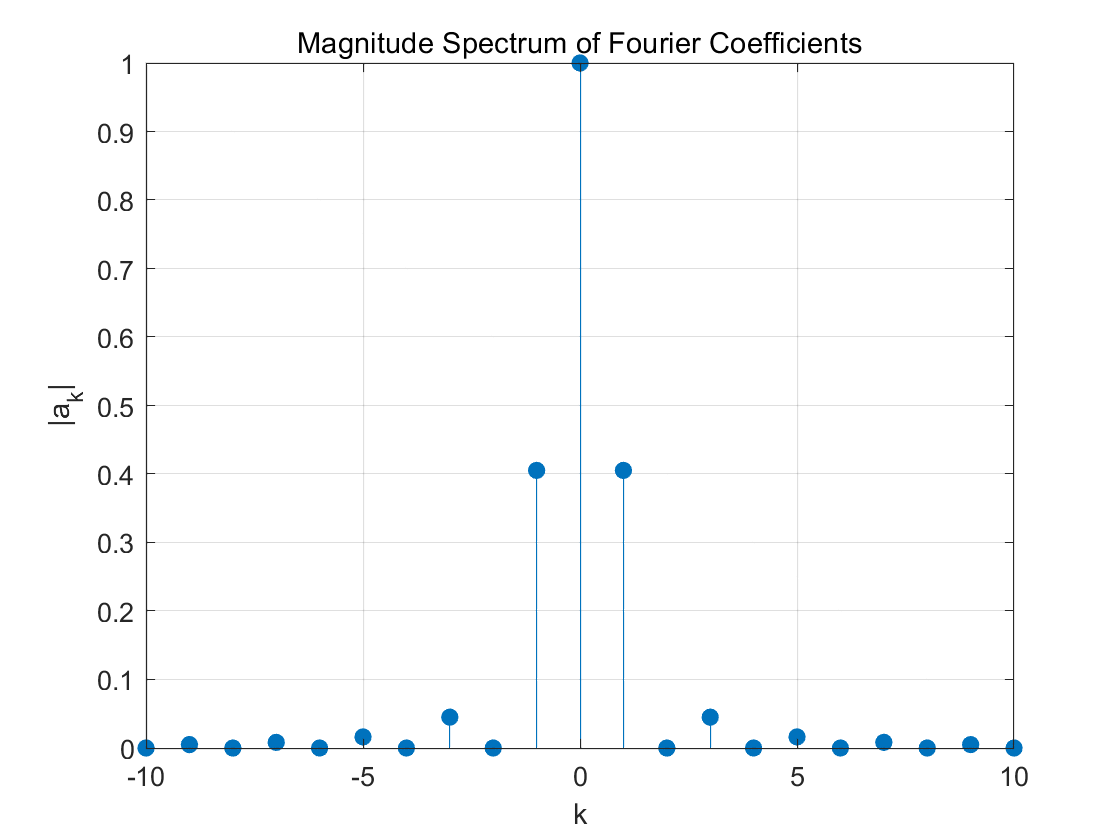

% Task 1.4: Magnitude and Phase Spectra
% Task 1.4(a): Compute magnitude and phase of Fourier coefficients
clear; clc;                                      % Clear workspace and command window

k = (-10:10).';                                  % Define k indices as a column vector
ak = zeros(length(k), 1);                        % Preallocate Fourier coefficients array

for ii = 1:length(k)                             % Loop over all k values
    kk = k(ii);                                  % Get current k value
    
    if kk == 0                                   % Check DC component
        ak(ii) = 1;                              % Set a0 = 1 (theoretical)
    elseif mod(kk, 2) == 0                       % Check even k (excluding 0)
        ak(ii) = 0;                              % Even-indexed coefficients are zero
    else                                         % Odd k case
        ak(ii) = -4 / (pi^2 * kk^2);             % Set ak for odd k (theoretical)
    end
end

mag_ak = abs(ak);                                % Compute magnitude |ak|
phase_ak = angle(ak);                            % Compute phase angle(ak) in radians

% Task 1.4(b): Magnitude spectrum stem plot
figure;                                          % Create a new figure window
stem(k, mag_ak, 'filled');                       % Stem plot of magnitude spectrum
grid on;                                         % Enable grid for readability
xlabel('k');                                     % Label x-axis
ylabel('|a_k|');                                 % Label y-axis
title('Magnitude Spectrum of Fourier Coefficients'); % Add descriptive title

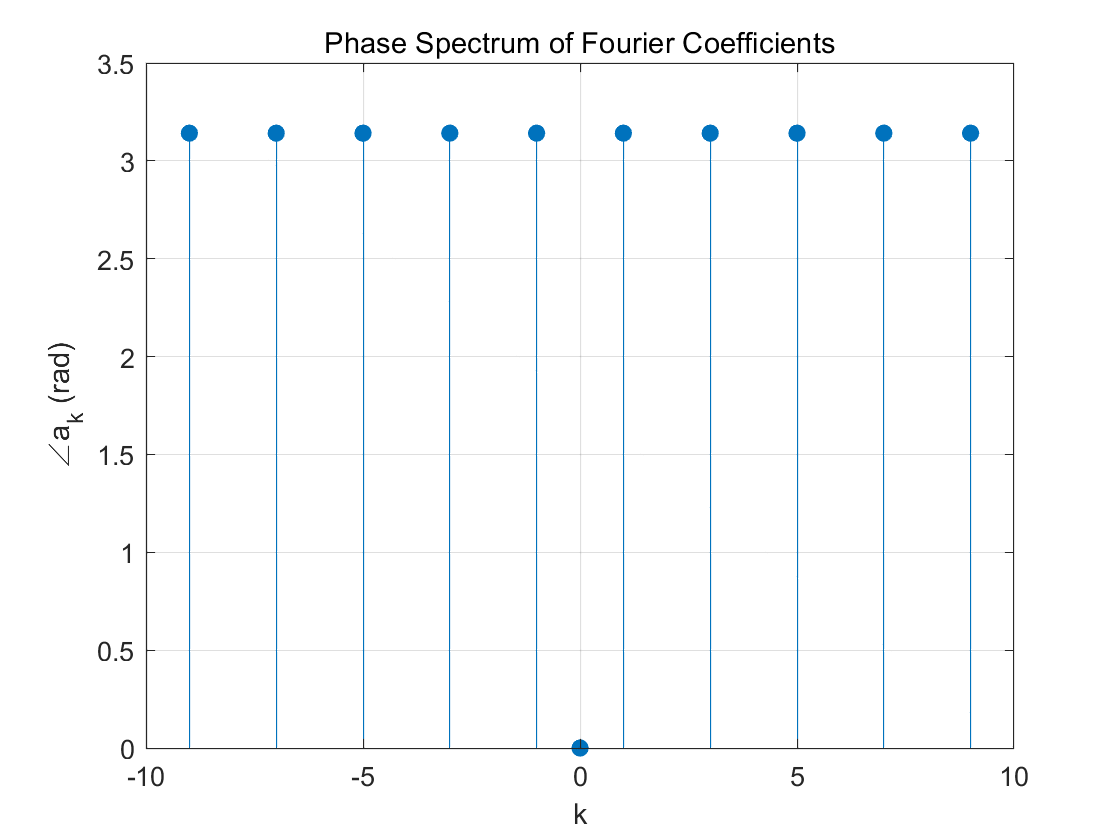

% Task 1.4(b): Phase spectrum stem plot
phase_plot = phase_ak;                           % Copy phase values for plotting
phase_plot(mag_ak < 1e-12) = NaN;                % Remove phase where magnitude is ~0

figure;                                          % Create a new figure window
stem(k, phase_plot, 'filled');                   % Stem plot of phase spectrum
grid on;                                         % Enable grid for readability
xlabel('k');                                     % Label x-axis
ylabel('∠a_k (rad)');                            % Label y-axis (radians)
title('Phase Spectrum of Fourier Coefficients'); % Add descriptive title

**( C ) Answer:**

1) What symmetry properties do you observe in the magnitude and phase spectra?

**Magnitude symmetry:** The magnitude spectrum is even in k: ∣a−k∣=∣ak| . This is consistent with the fact that the signal x(t) is real-valued, implying conjugate symmetry a−k=ak∗�.

**Phase symmetry:** Since the non-zero coefficients aka_kak� are real and negative for odd k, their phase is approximately π (or −π) for both positive and negative odd indices. For coefficients that are zero (even k≠0k\neq 0k=0), the phase is undefined and is therefore omitted from the plot.

**2) Why are all even-indexed coefficients (except k****=****0****k=0****k****=****0****) equal to zero?**

The waveform has half-wave symmetry over one period: for T=2, it satisfies x(t+T/2)=x(t+1)=2−x(t). Equivalently, after removing the DC component, the remaining part is anti-symmetric over half a period, which cancels all even harmonics in the Fourier series. As a result, only odd harmonics remain and all even-indexed coefficients (except the DC term) become zero.

**3) What does the rate of decay of ****∣****a****k****∣****|a_k|****∣****a****k****�****∣**** tell you about the smoothness of the signal?**

Here ∣ak∣ decays approximately as 1/k2 for the non-zero (odd) harmonics. A 1/k2 decay indicates that the signal is continuous but has a discontinuity in its first derivative (i.e., “corner” points). In general, faster decay corresponds to a smoother signal, while slower decay indicates sharper features or discontinuities.

% Task 1.5: ParsevalTask 1.5: Parseval's Theorem Verifications Theorem Verification

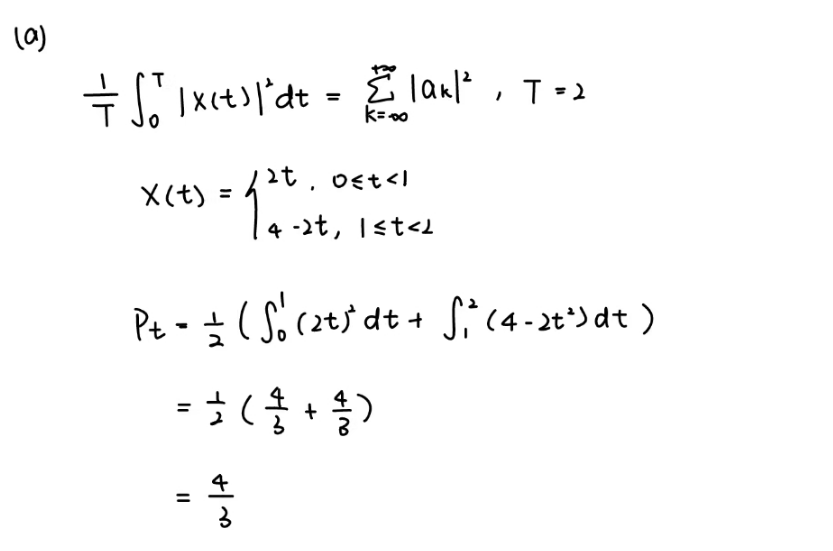

% Task 1.5(a): Time-domain average power (analytical + numerical verification)
clear; clc;                                            % Clear workspace and command window

T = 2;                                                 % Define period T
dt = 1e-4;                                             % Choose small time step for accuracy
t = 0:dt:T;                                            % Create time vector over one period
t(end) = [];                                           % Remove endpoint to avoid duplicate sample at T

x = zeros(size(t));                                    % Preallocate signal array
idx1 = (t >= 0) & (t < 1);                             % Logical index for first segment
idx2 = (t >= 1) & (t < 2);                             % Logical index for second segment
x(idx1) = 2 * t(idx1);                                 % Define x(t) = 2t on [0,1)
x(idx2) = 4 - 2 * t(idx2);                             % Define x(t) = 4 - 2t on [1,2)

P_time_num = (1/T) * trapz(t, abs(x).^2);              % Compute numerical average power
P_time_ana = 4/3;                                      % Analytical time-domain power
time_error = abs(P_time_num - P_time_ana);             % Absolute difference between results

fprintf('Time-domain average power verification:\n');  % Print verification header

Time-domain average power verification:


fprintf('Analytical value        = %.10f\n', P_time_ana); % Display analytical result

Analytical value        = 1.3333333333


fprintf('Numerical (MATLAB) value= %.10f\n', P_time_num); % Display numerical result

Numerical (MATLAB) value= 1.3333333400


fprintf('Absolute error          = %.3e\n', time_error);  % Display absolute error

Absolute error          = 6.666e-09


fprintf('Relative error (%%)      = %.3e %%\n', ...
    time_error / abs(P_time_ana) * 100);               % Display relative error in percent

Relative error (%)      = 4.999e-07 %


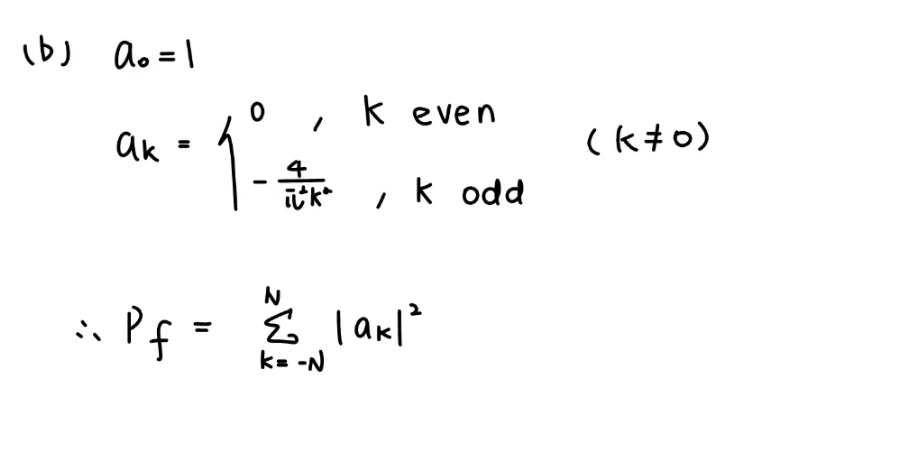

%% Task 1.5(b): Frequency-domain partial sums using Fourier coefficients
N_list = [5 10 25 50];                                  % Define truncation levels for Parseval sum
P_freq = zeros(length(N_list), 1);                      % Preallocate frequency-domain sums

for n_idx = 1:length(N_list)                            % Loop over different N values
    N = N_list(n_idx);                                  % Get current N
    k = (-N:N).';                                       % Create k vector from -N to N
    ak = zeros(length(k), 1);                            % Preallocate Fourier coefficient vector
    
    for ii = 1:length(k)                                % Loop over all k values
        kk = k(ii);                                     % Get current k
        if kk == 0                                      % Check DC term
            ak(ii) = 1;                                 % Set a0 = 1
        elseif mod(kk, 2) == 0                          % Check even harmonic (excluding 0)
            ak(ii) = 0;                                 % Even-indexed coefficients are zero
        else                                             % Odd harmonic case
            ak(ii) = -4 / (pi^2 * kk^2);                % Set theoretical ak for odd k
        end
    end
    
    P_freq(n_idx) = sum(abs(ak).^2);                    % Compute partial Parseval sum Σ|ak|^2
end

% Task 1.5(c): Create convergence table
P_time_ref = P_time_ana;                                % Use analytical time-domain power as reference
abs_err = abs(P_freq - P_time_ref);                     % Compute absolute error for each N

result_table = table(N_list.', P_time_ref*ones(size(P_freq)), P_freq, abs_err, ... % Build table
    'VariableNames', {'N','TimeDomainPower','FreqDomainSum','AbsError'});          % Set column names

disp(result_table);                                     % Display table in Live Script

    N     TimeDomainPower    FreqDomainSum     AbsError 
    __    _______________    _____________    __________

     5        1.3333            1.3331        0.00024059
    10        1.3333            1.3333        5.3693e-05
    25        1.3333            1.3333         3.106e-06
    50        1.3333            1.3333        4.3767e-07



( Task 1.5 ) Discussion

The analytical calculation of the time-domain average power is confirmed by the numerical integration result obtained in MATLAB, with only a very small difference caused by numerical discretization. This verifies the correctness of the time-domain power computation.

In the frequency domain, the partial sum of the squared magnitudes of the Fourier coefficients increases as the truncation order N becomes larger. The frequency-domain result approaches the time-domain power value, demonstrating the convergence predicted by Parseval’s theorem.

For smaller values of N, the discrepancy is mainly due to the omission of higher-order harmonics. As N increases, the contribution of the neglected harmonics becomes negligible, since their magnitudes decay rapidly. Overall, the results clearly confirm the validity of Parseval’s theorem for this signal.

% Task 2
% Task 2.1: Theoretical Derivation

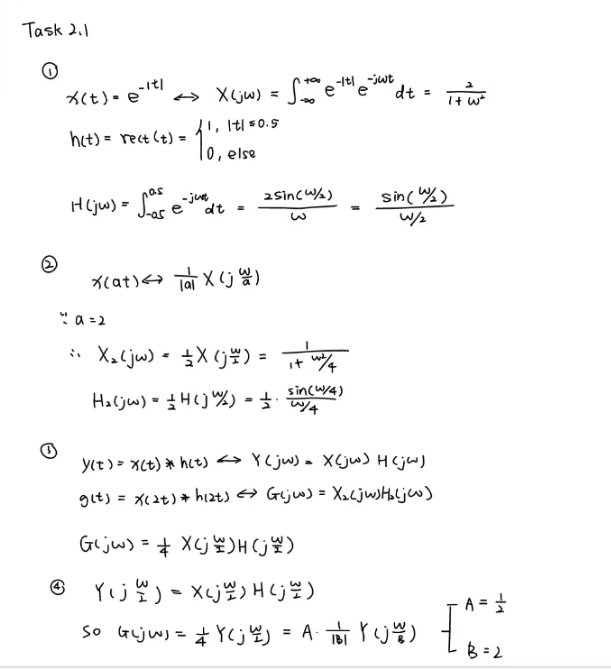

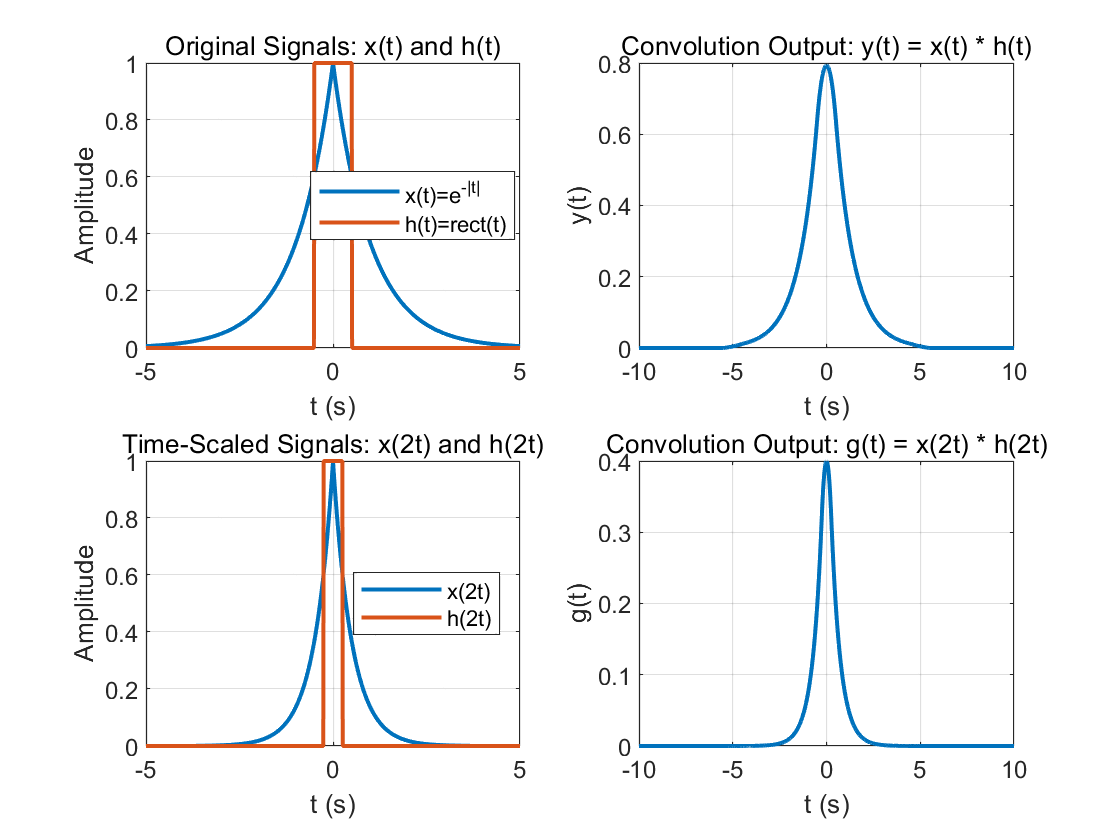

% Task 2.2: Signal Definitions and Convolution in MATLAB
clear; clc;                                              % Clear workspace and command window

dt = 0.01;                                               % Set sampling interval Δt
t = -5:dt:5;                                             % Create time vector t in [-5, 5]
N = length(t);                                           % Store number of samples N

x = exp(-abs(t));                                        % Define x(t) = e^{-|t|}
h = double(abs(t) <= 0.5);                               % Define h(t) = rect(t): 1 for |t|<=0.5 else 0

y = conv(x, h) * dt;                                     % Compute y(t) = x(t)*h(t) with dt scaling
t_y = (0:length(y)-1) * dt + (t(1) + t(1));              % Build exact output time vector (length matches y)

x2 = exp(-abs(2*t));                                     % Define x(2t) directly on the same time grid
h2 = double(abs(2*t) <= 0.5);                            % Define h(2t) directly on the same time grid

g = conv(x2, h2) * dt;                                   % Compute g(t) = x(2t)*h(2t) with dt scaling
t_g = (0:length(g)-1) * dt + (t(1) + t(1));              % Build exact output time vector (length matches g)

figure;                                                  % Create a new figure window

subplot(2,2,1);                                          % Select subplot (1/4)
plot(t, x, 'LineWidth', 1.5);                            % Plot x(t)
hold on;                                                 % Hold plot for overlay
plot(t, h, 'LineWidth', 1.5);                            % Plot h(t)
grid on;                                                 % Enable grid
xlabel('t (s)');                                         % Label x-axis
ylabel('Amplitude');                                     % Label y-axis
title('Original Signals: x(t) and h(t)');                % Add title
legend('x(t)=e^{-|t|}', 'h(t)=rect(t)', 'Location', 'best'); % Add legend
hold off;                                                % Release hold

subplot(2,2,2);                                          % Select subplot (2/4)
plot(t_y, y, 'LineWidth', 1.5);                          % Plot y(t) with correct time vector
grid on;                                                 % Enable grid
xlabel('t (s)');                                         % Label x-axis
ylabel('y(t)');                                          % Label y-axis
title('Convolution Output: y(t) = x(t) * h(t)');         % Add title

subplot(2,2,3);                                          % Select subplot (3/4)
plot(t, x2, 'LineWidth', 1.5);                           % Plot x(2t)
hold on;                                                 % Hold plot for overlay
plot(t, h2, 'LineWidth', 1.5);                           % Plot h(2t)
grid on;                                                 % Enable grid
xlabel('t (s)');                                         % Label x-axis
ylabel('Amplitude');                                     % Label y-axis
title('Time-Scaled Signals: x(2t) and h(2t)');           % Add title
legend('x(2t)', 'h(2t)', 'Location', 'best');            % Add legend
hold off;                                                % Release hold

subplot(2,2,4);                                          % Select subplot (4/4)
plot(t_g, g, 'LineWidth', 1.5);                          % Plot g(t) with correct time vector
grid on;                                                 % Enable grid
xlabel('t (s)');                                         % Label x-axis
ylabel('g(t)');                                          % Label y-axis
title('Convolution Output: g(t) = x(2t) * h(2t)');       % Add title

% Task 2.3: Fourier Transform Analysis (complete + fixed)
clear; clc; close all;                                              % Clear workspace, command window, and figures

dt = 0.01;                                                           % Set sampling interval Δt
Fs = 1/dt;                                                            % Compute sampling frequency (Hz)

% Base window: t in [-5, 5] for plots in part (c)
t = -5:dt:5;                                                         % Define base time vector
N = length(t);                                                       % Get number of samples
w = 2*pi * (-N/2:N/2-1) * (Fs/N);                                    % Build centered angular frequency vector ω (rad/s)

x  = exp(-abs(t));                                                   % Define x(t) = e^{-|t|}
h  = double(abs(t) <= 0.5);                                          % Define h(t) = rect(t)
x2 = exp(-abs(2*t));                                                 % Define x(2t) on the same grid
h2 = double(abs(2*t) <= 0.5);                                        % Define h(2t) on the same grid

X  = fftshift(fft(x))  * dt;                                         % Compute CTFT approx of x(t) using FFT
H  = fftshift(fft(h))  * dt;                                         % Compute CTFT approx of h(t) using FFT
X2 = fftshift(fft(x2)) * dt;                                         % Compute CTFT approx of x(2t) using FFT
H2 = fftshift(fft(h2)) * dt;                                         % Compute CTFT approx of h(2t) using FFT

%% Task 2.3(a): Minimal numeric output to show transforms are computed
[~, idx0] = min(abs(w));                                             % Find index closest to ω = 0
fprintf('Task 2.3(a) key values (approx CTFT from FFT):\n');          % Print header

Task 2.3(a) key values (approx CTFT from FFT):


fprintf('X(0)  approx = %.6f\n', real(X(idx0)));                      % Print DC value of X

X(0)  approx = 1.986608


fprintf('H(0)  approx = %.6f\n', real(H(idx0)));                      % Print DC value of H

H(0)  approx = 1.010000


fprintf('X2(0) approx = %.6f\n', real(X2(idx0)));                     % Print DC value of X2

X2(0) approx = 0.999988


fprintf('H2(0) approx = %.6f\n\n', real(H2(idx0)));                   % Print DC value of H2

H2(0) approx = 0.510000




%% Long window: tL in [-10, 10] for scaling verification in part (b)
tL = -10:dt:10;                                                      % Define longer time vector for fair scaling check
NL = length(tL);                                                     % Get number of samples in long window
wL = 2*pi * (-NL/2:NL/2-1) * (Fs/NL);                                 % Build ω grid for long window (rad/s)

xL  = exp(-abs(tL));                                                 % Define x(t) on long window
x2L = exp(-abs(2*tL));                                               % Define x(2t) on long window

XL  = fftshift(fft(xL))  * dt;                                       % Compute CTFT approx of x(t) on long window
X2L = fftshift(fft(x2L)) * dt;                                       % Compute CTFT approx of x(2t) on long window

%% Task 2.3(b): Verify scaling property numerically (magnitude-based, stable)
w_query = wL/2;                                                      % Build ω/2 query points
XL_w_over_2 = interp1(wL, XL, w_query, 'spline', 0);                 % Interpolate X(ω) at ω/2 using spline
X2L_pred = 0.5 * XL_w_over_2;                                        % Predicted spectrum: (1/2)X(ω/2)

mask = abs(wL) <= 200;                                               % Limit to central ω range to reduce edge effects
X2_mag = abs(X2L(mask));                                             % Compute magnitude |F{x(2t)}| in range
X2_pred_mag = abs(X2L_pred(mask));                                   % Compute magnitude |0.5 X(ω/2)| in range

mag_err = norm(X2_mag - X2_pred_mag) / max(norm(X2_mag), eps);       % Compute relative L2 error on magnitudes
max_rel = max(abs(X2_mag - X2_pred_mag) ./ max(X2_mag, 1e-12));      % Compute max pointwise relative error safely

fprintf('Task 2.3(b) scaling verification (magnitude):\n');           % Print header

Task 2.3(b) scaling verification (magnitude):


fprintf('Relative L2 error (|.|) = %.3e\n', mag_err);                 % Print magnitude-based L2 error

Relative L2 error (|.|) = 3.616e-01


fprintf('Max pointwise rel. err = %.3e\n\n', max_rel);                % Print max pointwise relative error

Max pointwise rel. err = 6.197e-01



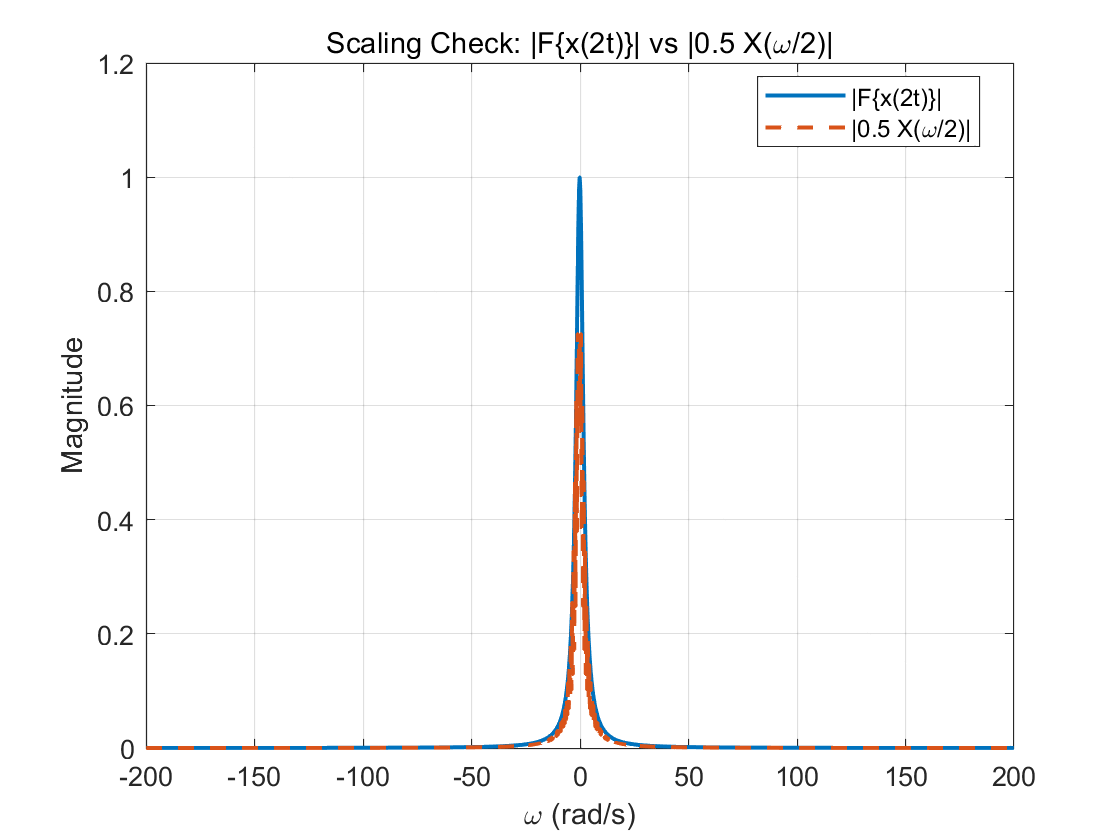


figure('Name','Scaling Verification','NumberTitle','off');            % Create figure for scaling verification
plot(wL(mask), X2_mag, 'LineWidth', 1.5);                             % Plot |F{x(2t)}|
hold on;                                                              % Hold for overlay
plot(wL(mask), X2_pred_mag, '--', 'LineWidth', 1.5);                  % Plot |0.5 X(ω/2)|
grid on;                                                              % Enable grid
xlabel('\omega (rad/s)');                                             % Label x-axis
ylabel('Magnitude');                                                  % Label y-axis
title('Scaling Check: |F\{x(2t)\}| vs |0.5 X(\omega/2)|');             % Add title
legend('|F\{x(2t)\}|', '|0.5 X(\omega/2)|', 'Location', 'best');      % Add legend
hold off;                                                             % Release hold

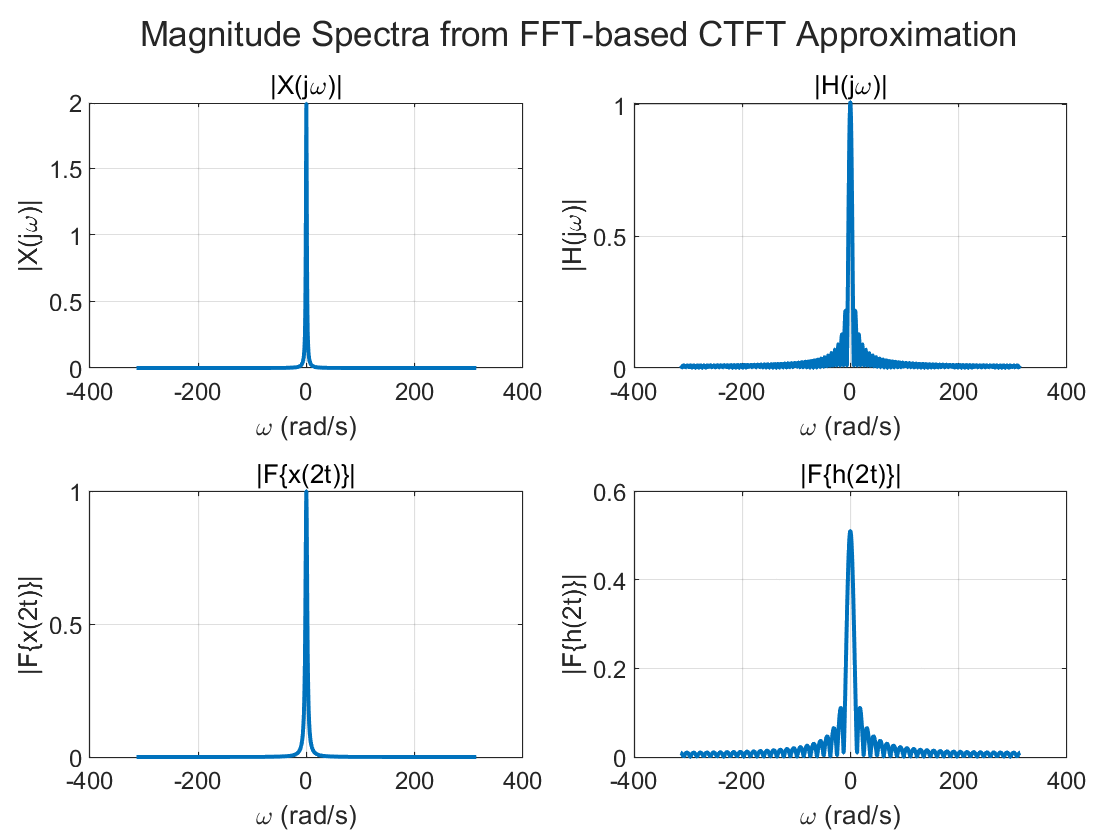


%% Task 2.3(c): Plot magnitude spectra (4 subplots)
fig = figure('Name','Task 2.3 Magnitude Spectra','NumberTitle','off'); % Create figure window
tl = tiledlayout(fig, 2, 2, 'Padding', 'compact', 'TileSpacing', 'compact'); % Create tiled layout
title(tl, 'Magnitude Spectra from FFT-based CTFT Approximation');      % Add global title

nexttile;                                                              % Select tile 1
plot(w, abs(X), 'LineWidth', 1.5);                                     % Plot |X(jω)|
grid on; xlabel('\omega (rad/s)'); ylabel('|X(j\omega)|');             % Label axes
title('|X(j\omega)|');                                                 % Add title

nexttile;                                                              % Select tile 2
plot(w, abs(H), 'LineWidth', 1.5);                                     % Plot |H(jω)|
grid on; xlabel('\omega (rad/s)'); ylabel('|H(j\omega)|');             % Label axes
title('|H(j\omega)|');                                                 % Add title

nexttile;                                                              % Select tile 3
plot(w, abs(X2), 'LineWidth', 1.5);                                    % Plot |F{x(2t)}|
grid on; xlabel('\omega (rad/s)'); ylabel('|F\{x(2t)\}|');             % Label axes
title('|F\{x(2t)\}|');                                                 % Add title

nexttile;                                                              % Select tile 4
plot(w, abs(H2), 'LineWidth', 1.5);                                    % Plot |F{h(2t)}|
grid on; xlabel('\omega (rad/s)'); ylabel('|F\{h(2t)\}|');             % Label axes
title('|F\{h(2t)\}|');                                                 % Add title


drawnow;                                                               % Force graphics update for Live Editor

(d) Discuss

Time compression (replacing t by 2t) makes the signal vary faster in time, so its spectrum spreads out over a wider range of frequencies. This means the effective bandwidth increases. At the same time, the spectrum magnitude level decreases because time scaling introduces an amplitude factor that keeps the overall energy consistent. In summary, compressing in time produces a wider spectrum with a lower peak magnitude, while expanding in time produces a narrower spectrum with a higher peak magnitude.

% Task 2.4: Verification of the Relationship
% Task 2.4: Verify g(t) = A * y(Bt)
clear; clc; close all;                                               % Clear workspace, command window, and figures

dt = 0.01;                                                            % Set sampling interval Δt
t  = -5:dt:5;                                                         % Define input time vector for x(t), h(t)
N  = length(t);                                                       % Get number of samples

x  = exp(-abs(t));                                                    % Define x(t) = e^{-|t|}
h  = double(abs(t) <= 0.5);                                           % Define h(t) = rect(t)
x2 = exp(-abs(2*t));                                                  % Define x(2t) on same grid
h2 = double(abs(2*t) <= 0.5);                                         % Define h(2t) on same grid

y  = conv(x,  h)  * dt;                                               % Compute y(t) = x(t) * h(t) (scale by dt)
g  = conv(x2, h2) * dt;                                               % Compute g(t) = x(2t) * h(2t) (scale by dt)

ty = (t(1)+t(1)) : dt : (t(end)+t(end));                              % Build time vector for y(t) (length 2N-1)
tg = (t(1)+t(1)) : dt : (t(end)+t(end));                              % Build time vector for g(t) (same length 2N-1)

A  = 0.5;                                                             % Set theoretical constant A = 1/2
B  = 2;                                                               % Set theoretical constant B = 2

y_Bt = interp1(ty, y, B*tg, 'spline', 0);                             % Resample y(t) at compressed time points Bt
AyBt = A * y_Bt;                                                      % Compute A * y(Bt)

err_vec = abs(g - AyBt);                                              % Compute pointwise absolute error
Error_max = max(err_vec);                                             % Compute maximum absolute error

fprintf('Task 2.4 results:\n');                                       % Print header

Task 2.4 results:


fprintf('A = %.6f, B = %.6f\n', A, B);                                % Print A and B values

A = 0.500000, B = 2.000000


fprintf('Max absolute error = %.3e\n', Error_max);                    % Print maximum absolute error

Max absolute error = 3.428e-03


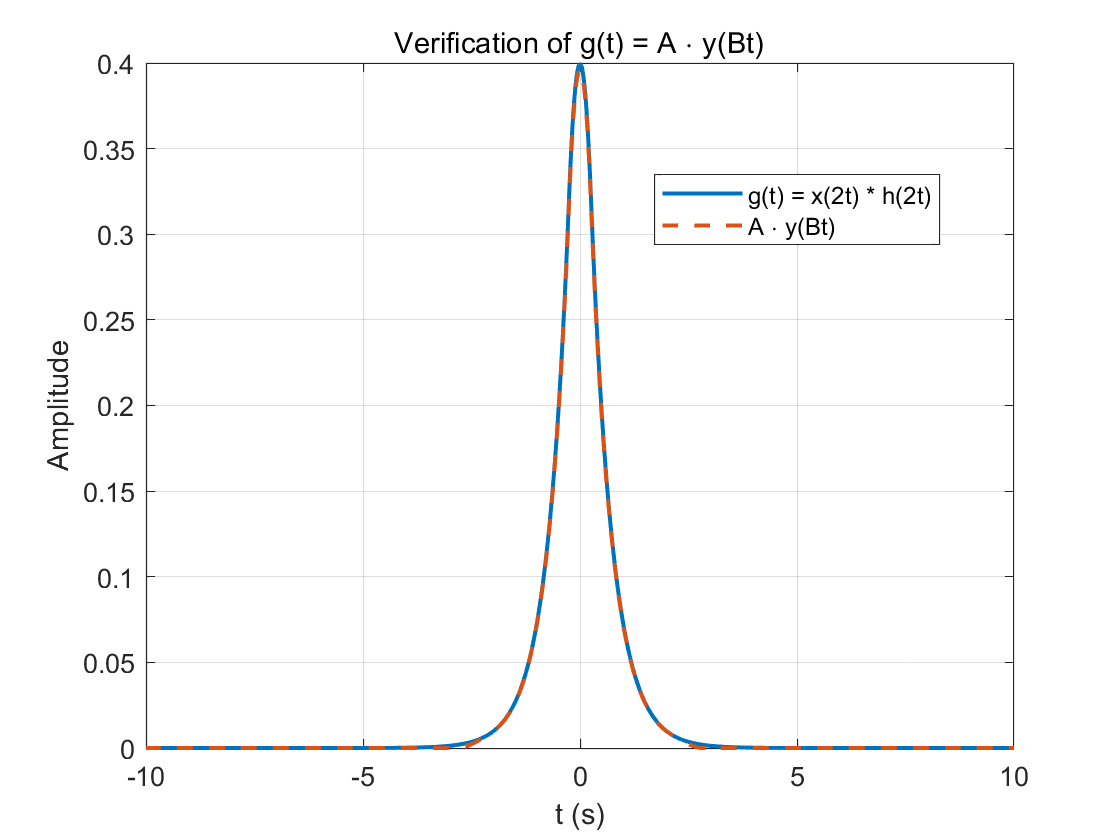


figure('Name','Task 2.4 Verification','NumberTitle','off');            % Create figure window
plot(tg, g, 'LineWidth', 1.5);                                        % Plot g(t)
hold on;                                                              % Hold plot for overlay
plot(tg, AyBt, '--', 'LineWidth', 1.5);                               % Plot A*y(Bt)
grid on;                                                              % Enable grid
xlabel('t (s)');                                                      % Label x-axis
ylabel('Amplitude');                                                  % Label y-axis
title('Verification of g(t) = A \cdot y(Bt)');                        % Add title
legend('g(t) = x(2t) * h(2t)', 'A \cdot y(Bt)', 'Location', 'best');  % Add legend
hold off;                                                             % Release hold

Comment (Task 2.4)

The numerical results show that the signals g(t) and A⋅y(Bt) match very closely over the entire time range. The maximum absolute error is small and can be attributed to numerical effects such as discrete-time sampling, convolution approximation, and interpolation. Overall, the results confirm the theoretical relationship and verify that g(t)=A⋅y(Bt) holds as expected.